`Pràctica`

`(a)` `Com canvia el nombre de condició d’aquesta matriu quan l’ordre creix? Presenta un estudi per n=5÷30.`

for tam=5:30;
    A = zeros(tam,tam);
    A(1,1) = -1;
    i = 1;
    j = 2;
    i2 = 2;
    j2 = 1;
    while i < tam;
        A(i,j) = 1;
        A(i2,j) = 4;
        A(i2,j2) = 1;
        i = i+1;
        j = j+1;
        i2 = i2+1;
        j2 = j2+1;
    end
    A(tam,tam) = -1;
    for i=1:tam;
        if i == 1;
            b = [0];
        elseif i == tam;
            b = [b;0];
        else 
            b = [b;6];
        end    
    end
    if tam == 5;
        R = [tam,cond(A)]; 
        x = [tam];
        y = [cond(A)];
    else R = [R;tam,cond(A)];
        x = [x;tam];
        y = [y;cond(A)];
    end
end
Ta=array2table(R,'VariableNames',{'tam','cond'})

Ta = 26×2 table
    tam     cond 
    ___    ______

     5     4.6062
     6     4.7238
     7     4.7998
     8     4.8494
     9     4.8829
    10     4.9064
    11     4.9235
    12     4.9363
    13     4.9462
    14     4.9539
    15     4.9601
    16     4.9651
    17     4.9693
    18     4.9727
    19     4.9756
    20      4.978


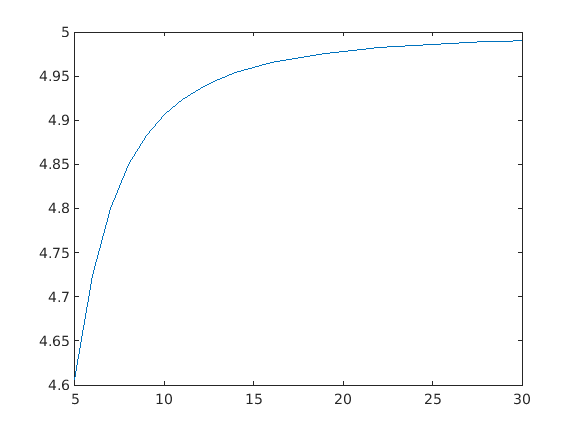

Pa=plot(x,y)

A la taula **Ta** podem veure com a mesura que augmenta l'ordre de la matriu, també augmenta el nombre de condició. A la gràfica **Pa** podem veure com l'augment de la condició s'aproxima molt a una funció logarítimica i que a partir d'un cert ordre prou gran de matriu, l'**augment **del nombre de condició tendeix a disminuir.

`(b)`` Resoleu el sistema lineal 𝐴𝑥=𝑏Ax=b per eliminació gaussiana sense pivotament.`

format long
for tam=5:30;
    A = zeros(tam,tam);
    A(1,1) = -1;
    i = 1;
    j = 2;
    i2 = 2;
    j2 = 1;
    while i < tam;
        A(i,j) = 1;
        A(i2,j) = 4;
        A(i2,j2) = 1;
        i = i+1;
        j = j+1;
        i2 = i2+1;
        j2 = j2+1;
    end
    A(tam,tam) = -1;
    for i=1:tam;
        if i == 1;
            b = [0];
        elseif i == tam;
            b = [b;0];
        else 
            b = [b;6];
        end    
    end
    tic
    [L,U,P] = lu(A);
    prova = norm(P*A-L*U,1);
    %la solució del sistema és en dos etapes, primer resolem Ly=Pb i després  Ux=y
    y = linsolve(L,P*b); xs = linsolve(U,y);  % linsolve més eficient
    t = toc;
    if tam == 5;
        R = [tam,t];
        TA = [t];
    else
        R = [R;tam,t];
        TA = [TA;t];
    end
end
Tb=array2table(R,'VariableNames',{'tam','t'})

Tb = 26×2 table
    tam       t    
    ___    ________

     5     0.000433
     6     0.000204
     7     0.000348
     8     0.000133
     9     0.001108
    10      5.3e-05
    11      2.7e-05
    12      2.5e-05
    13      2.7e-05
    14      2.8e-05
    15      3.1e-05
    16      3.1e-05
    17      5.3e-05
    18      4.5e-05
    19      4.6e-05
    20      4.7e-05


`(c)`` Resoleu el sistema lineal 𝐴𝑥=𝑏 fent ús de les funcions de Matlab® ``decompositon`` i ``linsolve``.`

format long
for tam=5:30
    A = zeros(tam,tam);
    A(1,1) = -1;
    i = 1;
    j = 2;
    i2 = 2;
    j2 = 1;
    while i < tam;
        A(i,j) = 1;
        A(i2,j) = 4;
        A(i2,j2) = 1;
        i = i+1;
        j = j+1;
        i2 = i2+1;
        j2 = j2+1;
    end
    A(tam,tam) = -1;
    for i=1:tam;
        if i == 1;
            b = [0];
        elseif i == tam;
            b = [b;0];
        else 
            b = [b;6];
        end    
    end
    tic
    da = decomposition(A);
    da\b;
    td = toc;
    tic
    linsolve(A,b);
    tl = toc;
    if tam == 5;
        R = [tam,td,tl];
        TD = [td];
        TL = [tl];
    else
        R = [R;tam,td,tl];
        TD = [TD;td];
        TL = [TL;tl];
    end
end
Tc=array2table(R,'VariableNames',{'tam','td','tl'})

Tc = 26×3 table
    tam       td          tl   
    ___    ________    ________

     5     0.000503     8.7e-05
     6     0.000418     5.9e-05
     7     0.000502     6.1e-05
     8     0.000307     5.4e-05
     9     0.000676    0.000331
    10     0.000195     1.9e-05
    11     0.000129     1.4e-05
    12     0.000117     1.4e-05
    13     0.000113     1.3e-05
    14     0.000132     1.5e-05
    15     0.000117     1.4e-05
    16     0.000113     1.5e-05
    17     0.000115     2.4e-05
    18      0.00012     2.2e-05
    19     0.000116     2.1e-05
    20     0.000116     2.2e-05


`(d)`` Resoleu el sistema lineal 𝐴𝑥=𝑏Ax=b pel mètode de Gauss-Seidel.`

format long
for tam=5:30
    A = zeros(tam,tam);
    A(1,1) = -1;
    i = 1;
    j = 2;
    i2 = 2;
    j2 = 1;
    while i < tam;
        A(i,j) = 1;
        A(i2,j) = 4;
        A(i2,j2) = 1;
        i = i+1;
        j = j+1;
        i2 = i2+1;
        j2 = j2+1;
    end
    A(tam,tam) = -1;
    for i=1:tam;
        if i == 1;
            b = [0];
        elseif i == tam;
            b = [b;0];
        else 
            b = [b;6];
        end    
    end
    tic
    D = diag(diag(A)); 
    L = tril(A-D); 
    U = triu(A-D);
    DI = inv(D+L);
    Bgs =-DI*U;
    cgs = DI*b;
    rhogs = abs(eigs(Bgs,1));        
    if rhogs < 1;
        k = 0;
        xs = zeros(size(b));
        r =norm(A*xs-b,1);
        while (k < 100 && r > 5.0e-4);
            k=k+1;
            xs = Bgs*xs+cgs;
            r =norm(A*xs-b,1);
        end
        %fprintf('métode de Gauss-Seidel convergent, en k = %d, el residu és %5.4g i el vector solució és\n',k,r);
        xs;
    %else
        %fprintf('métode de Gauss-Seidel no convergent');
    end 
    t = toc;
    if tam == 5;
        R = [tam,t];
        TG = [t];
    else
        R = [R;tam,t];
        TG = [TG;t];
    end
end
Td=array2table(R,'VariableNames',{'x','t'})

Td = 26×2 table
    x        t    
    __    ________

     5    0.003109
     6    0.000733
     7    0.000911
     8    0.000565
     9    0.002456
    10    0.000436
    11    0.000331
    12    0.000316
    13     0.00042
    14    0.000381
    15    0.000347
    16     0.00039
    17     0.00037
    18    0.000376
    19    0.000378
    20    0.000401


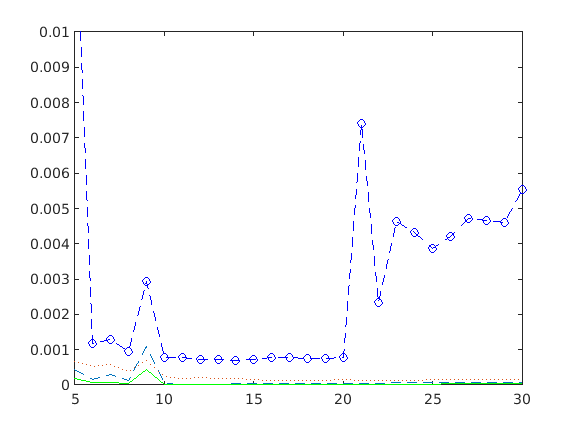

Pd=plot(x,TA,'--',x,TD,':',x,TL,'g',x,TG,'b--o')

xlim([5.0 30.0])
ylim([0.0000 0.010])

`(f)`` Comenteu els avantatges i els inconvenients dels tres mètodes i l’evolució dels resultats quan 𝑛n es fa gran.`

- Eliminació gaussiana sense pivotament (Factorització LU)

- **Inconvenients**

            Si algún menor principal és zero, pot no existir la descomposició LU.

- **Avantatges** 

            1. Per a qualsevol matriu no singular, les files poden ser reordenades de tal manera que existeixi una descomposició LU.

            2. És més ràpid i convenient per resoldre múltiples vegades les equacions per diferents b sense haver d'aplicar l’eliminació gaussiana cada vegada.

          2.  Decomposition i linsolve 

            Decomposition és típicament més ràpid i és molt útil per a resoldre problemes que necessiten solucions repetidament ja que la descomposició de la matriu només s’ha de fer una vegada.

            Linsolve utilitza la factorització LU amb pivotament parcial i per els altres casos utilitza factorització QR amb pivotament per columna. La factorització QR és més costosa que la LU.

          3. Gauss-Seidel

            En general, si convergeix el mètode Jacobi, el mètode de Gauss-Seidel convergirà més ràpidament que el mètode Jacobi, tot i que encara és relativament lent.

            De fet, aquest és el mètode més lent (es pot comprovar a la gràfica Pd) i la que dòna més errors d'aproximació en la solució.

          4. Evolució dels resultats quan *n* es fa gran

            La solució trobada pels diferents mètodes són bastants similars per a tots els ordres de matriu i no hi ha gaire errors menys en el cas del Gauss-Seidel. 

            Amb aquest métode, hi han més errors d'aproximació quan més petit és l'ordre.